# Armado algoritmo

%%%Fotos    %%%%cambiar por un 
[rgb, nube, profd, ir]=realSense.step;   %saco las fotos

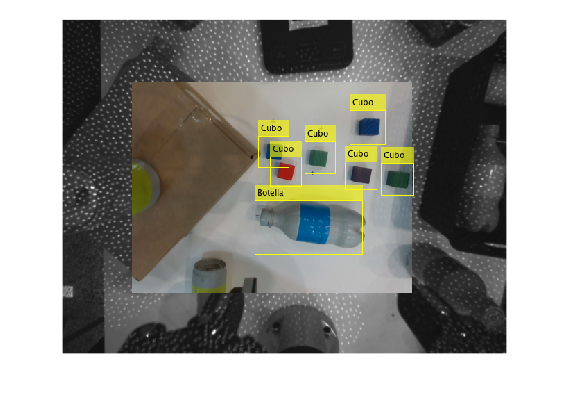

load("info_nube_puntos.mat")
rgb = foto_original;
nube = foto_prof;
ir = ir;
imshow(rgb)

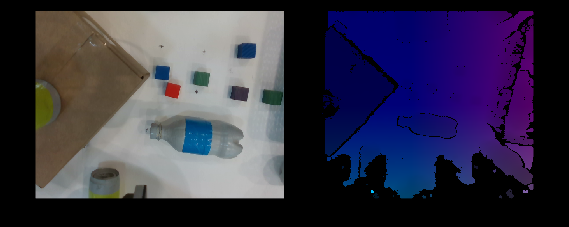


% % guardar_inf(rgb,nube,profd,ir,H_Actual_Mesa,i)
% ab=ab+1;
% deptFotoprueba{ab}=profd;
% colorImagefoto{ab}=rgb;
% pCLOUD{ab}=nube;
% irIMAGEFOTO{ab} = ir;
% H_actualB{ab}=H_Actual_Mesa;
% save('datos18_18','pCLOUD','deptFotoprueba','colorImagefoto',"irIMAGEFOTO","H_actualB")
imshowpair(rgb,nube,'montage')

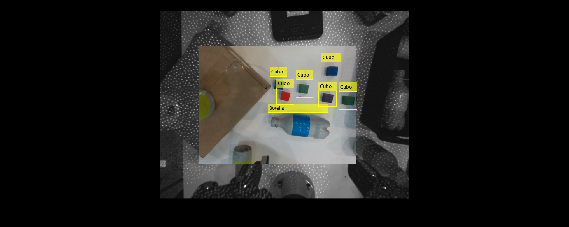

angulo_Gripper = 0;
[outputImg] = alineado(ir,rgb);
[I,I2,bboxes,scores,labels] = fotos_brasil(outputImg,detector);
imshow(I2)

 if isempty(labels)
        ('Zona limpia u objeto no detectado')
        % break;
 end


    % Selecciona la mejor detección por prioridad
label2 = string(labels)

label2 = 7×1 string array
    "Botella"
    "Cubo"
    "Cubo"
    "Cubo"
    "Cubo"
    "Cubo"
    "Cubo"


m = buscarIndicePrioritario_Brasil(label2)

m = 1

%%% Paso 5 Seleccionamos el objeto con mayor precisión
m=4;
    max_label=labels(m,1);
    max_label = string(max_label);
    disp(max_label)

Cubo


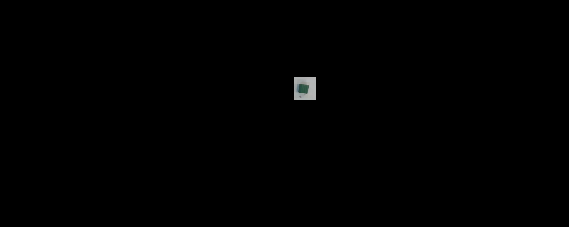

    prof= nube;
    
    %%% Paso 6 Hallamos caja del objeto seleccionado
    bbox = round(bboxes(m,:));
    %%% Paso 7 Creamos una matriz de 0's del tamaño de la imagen 
    MaskYolo = zeros(size(prof));
    %%% Ṕaso 8 convertimos la matriz en NaN%% MaskYolo(:,:) = nan('single');
    % Paso 9 Insertamos una máscara de acuerdo a las dimensiones de la caja
    imgWidth = 640;
    imgHeight = 480;
    % Margen opcional alrededor del bbox
    margin = 5;
    
    % Coordenadas originales del bbox
    x1 = max(1, bbox(1) - margin);
    y1 = max(1, bbox(2) - margin);
    x2 = min(imgWidth, bbox(1) + bbox(3) + margin);
    y2 = min(imgHeight, bbox(2) + bbox(4) + margin);
    
    % Crear máscara vacía
    MaskYolo = zeros(imgHeight, imgWidth);
    
    % Asignar valor 1 dentro del área del bbox
    MaskYolo(y1:y2, x1:x2) = 1;
    
    %%
    
    try 
        % MaskYolo(bbox(2)-5:bbox(2)+bbox(4)+5,bbox(1)-5:bbox(1)+bbox(3)+5) = 1;
        % mask3D = repmat(MaskYolo, [1 1 size(I,3)]); % convierte la máscara a 3D
        I_mask1 = bsxfun(@times, I, cast(MaskYolo, 'like', I));
       
    catch
        try
            MaskYolo(bbox(2):bbox(2)+bbox(4),bbox(1):bbox(1)+bbox(3)) = 1;
            % mask3D = repmat(MaskYolo, [1 1 size(I,3)]); % convierte la máscara a 3D
            I_mask1 = bsxfun(@times, I, cast(MaskYolo, 'like', I));
        catch
            try
                MaskYolo(bbox(2)+5:bbox(2)+bbox(4)-5,bbox(1)+5:bbox(1)+bbox(3)-5) = 1;
                % mask3D = repmat(MaskYolo, [1 1 size(I,3)]); % convierte la máscara a 3D
                I_mask1 = bsxfun(@times, I, cast(MaskYolo, 'like', I));
            catch
                MaskYolo(bbox(2)+10:bbox(2)+bbox(4)-10,bbox(1)+10:bbox(1)+bbox(3)-10) = 1;
                % mask3D = repmat(MaskYolo, [1 1 size(I,3)]); % convierte la máscara a 3D
                I_mask1 = bsxfun(@times, I, cast(MaskYolo, 'like', I));
            end
        end
    end
    % imshow(MaskYolo)
    imshow(I_mask1)

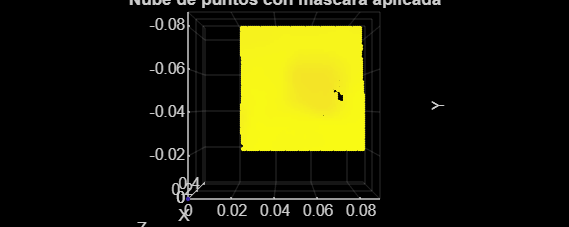

    mask = logical(MaskYolo);
    
    % 2. Expandir la máscara para las 3 coordenadas
    mask3D = repmat(mask, [1 1 3]);  % tamaño: 480x640x3
    
    % 3. Aplicar la máscara: poner NaN donde no se quiere conservar
    prof(~mask3D) = NaN;
    % prof(:,:,3) = prof(:,:,3);
    % 4. Convertir a objeto pointCloud
    ptCloudMasked = pointCloud(prof);
    % ptCloudMasked = pointCloud(dept);
    ptCloudMasked = removeInvalidPoints(ptCloudMasked);
    % 5. Visualizar
    % pcshow(ptCloudMasked);
    pcshow(ptCloudMasked, VerticalAxis="Y", VerticalAxisDir="Up", ViewPlane="YX",MarkerSize=50)
    title('Nube de puntos con máscara aplicada');
    xlabel('X')
    ylabel('Y')
    zlabel('Z')

#### Transformaciones

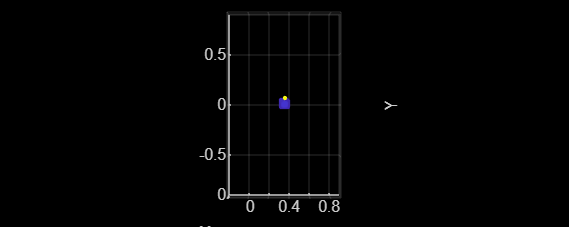

    TGripperRobot = H_actual;
    
    % TCameraGripper = [1 0 0   0.00;... 
    %                   0 1 0  -0.06;...
    %                   0 0 1  -0.10
    %                   0 0 0   1.00];  %%Transformada de cámara simulacion ¿
    TCameraGripper =  [0.999538308921320	-0.0291243522750580	-0.00865685296549709	-0.0319758672156050;
                       0.0300542118368598	0.989565288697892	0.140915874744907	-0.0756534035706355;
                       0.00446243762679872	-0.141110990035558	0.989983724685215	-0.111774042001070;
                        0	0	0	1];
    T= [0 -1 0 0; 
        1 0 0 0; 
        0 0 1 0;
        0 0 0 1];
    % ptCloudMasked = pointCloud(dept);
    % ptCloudMasked = ptCloudMasked;
    tform = affinetform3d(TGripperRobot*TCameraGripper);
    % ptCloudFiltered = pctransform(ptCloudFiltered,tform);
    ptCloudFiltered = pctransform(ptCloudMasked,tform);
    pcshow(ptCloudFiltered, VerticalAxis="Y", VerticalAxisDir="UP", ViewPlane="XY",MarkerSize=50)
    
    xlabel('X')
    ylabel('Y')
    zlabel('Z')
    xlim([-0.20,0.90])
    ylim([-0.90,0.90])

    %%
    

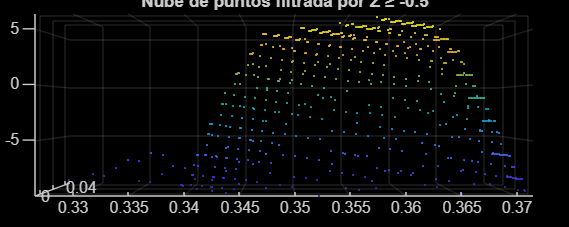


     xyz = ptCloudFiltered.Location;  % cada fila es [X Y Z]
    
    % Crear máscara lógica para Z >= -0.5
    z = xyz(:,3);
    zMask = (z >= -0.01) & (z <= 0.3);  % valores válidos465
    % zMask = (z >= -0.4) & (z <= -0.3);  % valores válidos
    % Aplicar máscara: poner NaN donde Z < -0.5
    xyz(~zMask, :) = NaN;
    
    % Crear nueva nube de puntos filtrada
    ptCloudFiltered = pointCloud(xyz);
    
    % (Opcional) aplicar también a color si existe
    if ~isempty(ptCloudFiltered.Color)
        rgb = ptCloudFiltered.Color;  % tamaño: N x 3
        rgb(~zMask, :) = 0;    % poner negro en los descartados
        ptCloudFiltered.Color = rgb;
    end
    
    % Visualizar
    pcshow(ptCloudFiltered);
    title('Nube de puntos filtrada por Z ≥ -0.5');

    %%

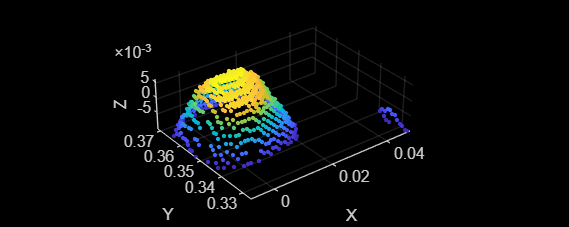

R = [0 1 0;
     1 0 0;
     0 0 1];
T = [R, [0;0;0]; 0 0 0 1];
ptCloudFixedj = pctransform(ptCloudFiltered, affine3d(T'));
pcshow(ptCloudFixedj, VerticalAxis="Y", VerticalAxisDir="UP", ViewPlane="XY",MarkerSize=50)
xlabel('X')
    ylabel('Y')
    zlabel('Z')

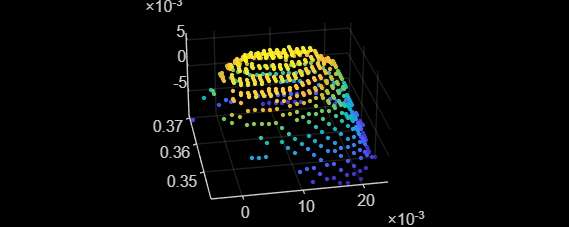

ptCloudFiltered2 = pcdenoise(ptCloudFixedj, 'Threshold', 0.5);
pcshow(ptCloudFiltered2, VerticalAxis="Y", VerticalAxisDir="UP", ViewPlane="XY",MarkerSize=50)

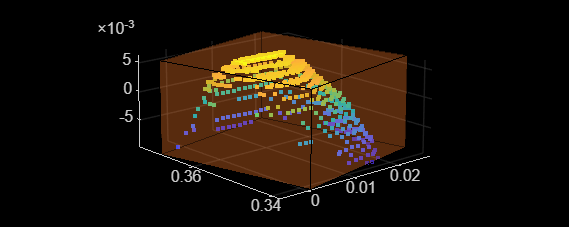


    model = pcfitcuboid(ptCloudFiltered2);
    plot(model)

    OrientacionObjeto = model.Orientation(1,3) *pi/180

OrientacionObjeto = -1.3614

    x2 = model.Center(1,1)

x2 = 0.0110

    y2 = model.Center(1,2)

y2 = 0.3563

    z2 = model.Center(1,3)

z2 = -0.0017

    %